clear;clc;close all;rng('default');
rng(0);

## Prepare images for training (only normal images are required）

imdsTrain = imageDatastore('trainingimage','IncludeSubfolders',true);

## Data Augmentation (Optional) and Using image Patch

% augmenter = imageDataAugmenter('RandXReflection',true,'RandYReflection',true);% ,...
% 'RandXTranslation', [-10 10], 'RandYTranslation', [-10 10], 'RandRotation', [-180 180]);
Imgsize = [720 1280];
BlockSize = [240 256];
% extract patch image
dsTrain = randomPatchExtractionDatastore(imdsTrain,imdsTrain,BlockSize,'PatchesPerImage',16'); % ,'DataAugmentation',augmenter);

## Visualize the patched images

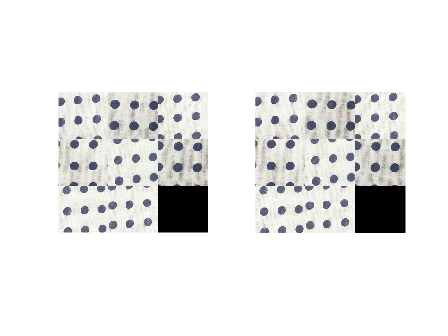

minibatch = preview(dsTrain);
figure,
subplot(1,2,1),montage(minibatch.InputImage);
subplot(1,2,2),montage(minibatch.ResponseImage);shg

## Define networks

inputsize = [BlockSize 3];
numClasses = 3;
% define vgg16-based segnet and customize it for image output
lgraph = segnetLayers(inputsize,numClasses,'vgg16');

Error using segnetLayers>iCheckIfVGG16AddOnIsAvailable (line 616)
This function requires Deep Learning Toolbox Model for VGG-16 Network. Please install this using the Add-On Explorer.
Error in segnetLayers (line 180)
            iCheckIfVGG16AddOnIsAvailable();

lgraph = removeLayers(lgraph,{'softmax','pixelLabels'});
lgraph = addLayers(lgraph,regressionLayer('Name','regressionLayer'));
lgraph = connectLayers(lgraph,'decoder1_relu_1','regressionLayer');

## set up options and train a network

options = trainingOptions('adam', ...
    'InitialLearnRate',20,...
    'MaxEpochs',30, ...
    'Shuffle','never',...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.9, ...
    'LearnRateDropPeriod',5, ...
    'MiniBatchSize',8, ...
    'Plots','training-progress', ...
    'Verbose',false);
dotraining = true;
if dotraining
    % It takes 30 minute with Titan X 
    net = trainNetwork(dsTrain,lgraph,options);
    save(['net.mat'],'net');
else
    load net;
end

## Prepare images for test

imdsTest = imageDatastore('testimage','IncludeSubfolders',true,'LabelSource','foldernames');

## Predict image using trained network

MxN = Imgsize./BlockSize;
% Prepare variables
I_All = uint8(zeros(Imgsize(1),Imgsize(2),3,numel(imdsTest.Files)));
Predicted_All = uint8(zeros(Imgsize(1),Imgsize(2),3,numel(imdsTest.Files)));
I_big =uint8(zeros(Imgsize(1),Imgsize(2),3));
Predicted_big =uint8(zeros(720,1280,3));

for nn=1:numel(imdsTest.Files)
    % Read image
    I_big = read(imdsTest);
    % process each block
    fun = @(block_struct) predict(net,block_struct.data);
    Predicted_big = uint8(blockproc(I_big,BlockSize,fun));
    % Stack images
    I_All(:,:,:,nn) = I_big;
    Predicted_All(:,:,:,nn) = Predicted_big;
    % show the pair of input and output images
    figure,imshowpair(I_big,Predicted_big,'montage');shg
end

## Evaluate the model with abomal images

convert RGB to LAB and calculate difference

subt = single(rgb2lab(I_All))-single(rgb2lab(Predicted_All));
eval = subt;
% Calculate absolute value
evalmed = median(eval,[1 2]);
normeval = abs(eval - evalmed);
% integrate errors of each LAB.
normeval2 = uint8(squeeze(sum(normeval,3)));

## remove noise and visualize the result

BW = ~(normeval2 < 20);
BW = bwareaopen(BW,50,4);
BW = imdilate(BW,ones(30));
BW = imclearborder(BW,4);
Color = {'r','r','r','r','b'};
f1 = figure;
f2 = figure;
% show the result
for k = 1:numel(imdsTest.Files)
    figure(f1), subplot(3,2,k), imshowpair(uint8(I_All(:,:,:,k)),BW(:,:,k),'montage');shg
    title(imdsTest.Labels(k),'FontSize',20,'Color', Color{k});
    figure(f2),subplot(3,2,k), imshowpair(uint8(I_All(:,:,:,k)),BW(:,:,k));shg
    title(imdsTest.Labels(k),'FontSize',20,'Color', Color{k});
end

*Copyright 2019 The MathWorks, Inc.*